Calcolo del valore del polinomio in un punto

myLagrange = @(x) ...
    ((log(0.4) * (x - 0.5) * (x - 0.7) * (x -0.8) / (-0.0120)) + ...
    (log(0.5) * (x - 0.4) * (x - 0.7) * (x - 0.8) / (0.0060)) + ...
    (log(0.7) * (x - 0.4) * (x - 0.5) * (x - 0.8) / (-0.0060)) + ...
    (log(0.8) * (x - 0.4) * (x - 0.5) * (x - 0.7) / (0.0120)))

myLagrange = function_handle with value:
    @(x)((log(0.4)*(x-0.5)*(x-0.7)*(x-0.8)/(-0.0120))+(log(0.5)*(x-0.4)*(x-0.7)*(x-0.8)/(0.0060))+(log(0.7)*(x-0.4)*(x-0.5)*(x-0.8)/(-0.0060))+(log(0.8)*(x-0.4)*(x-0.5)*(x-0.7)/(0.0120)))


Voglio calcolarla nel punto x = 0.6

res = myLagrange(0.6);
trueRes = log(0.6);

fprintf("Lagrange %g\nLn %g\n",res,trueRes);

Lagrange -0.509976
Ln -0.510826


Dobbiamo fare la derivata 4 della funzione f(x):

derivata4 = @(x)...
    -6./(x.^4)

derivata4 = function_handle with value:
    @(x)-6./(x.^4)



R = @(x,x1) ((x - 0.4) * (x - 0.5) * (x - 0.7) * (x - 0.8) * derivata4(x1))

R = function_handle with value:
    @(x,x1)((x-0.4)*(x-0.5)*(x-0.7)*(x-0.8)*derivata4(x1))


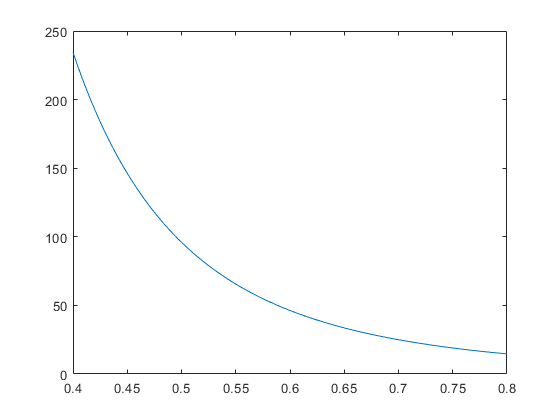


space = linspace(0.4,0.8);
y = abs(derivata4(space));

plot(space,y);


max = abs(derivata4(0.4))

max = 234.3750


Rabs = @(x) ((x - 0.4) * (x - 0.5) * (x - 0.7) * (x - 0.8) * max / factorial(4))

Rabs = function_handle with value:
    @(x)((x-0.4)*(x-0.5)*(x-0.7)*(x-0.8)*max/factorial(4))



Err = Rabs(0.6);
fprintf("errore stimato: %g\nerrore da differenza: %g\n",Err,abs(trueRes-res));

errore stimato: 0.00390625
errore da differenza: 0.000849921
